# Plot Dates and Times

This example shows how to create line plots with dates and times that are stored as `datetime` and `duration` arrays. The `datetime` data type represents points in time, such as August 24, 2020, 10:50:30 a.m., while the `duration` data type represents lengths of time, such as 12 hours and 30 minutes. Most plotting functions accept `datetime` and `duration` arrays as *x*-, *y*-, and *z*-coordinates and show tick values with appropriate date and time units. You can specify your own axis limits and tick values using `datetime` and `duration` values. You can also change the format of tick values to show date and time units of your choice. Data tips show `datetime` and `duration` values for cursor positions on a plot, and you can export those values to workspace variables. When you read data from a spreadsheet or comma-separated value (CSV) file, you can include the date and time data in your plots.

## Plot Date and Time Data

You can plot `datetime` and `duration` arrays without converting them to numeric arrays. Most plotting functions accept `datetime` and `duration` arrays as input arguments.

For example, plot a data set that has `datetime` values on the *x*-axis and numeric values on the *y*-axis. The *x*-coordinates are the `datetime` values for every day in June and July 2021. The plot automatically displays tick values with an appropriate format on the *x*-axis. In this case, the appropriate format shows month names and day numbers with the year.

XDates = [datetime(2021,6,1:30) datetime(2021,7,1:31)];
YNumsForXDates = sin(0:0.1:6);
plot(XDates,YNumsForXDates)

Similarly, plot a data set that has `duration` values on the *x*-axis. To create a `duration` array in units of seconds, use the `seconds` function.

XTimes = seconds(0:120);
YNumsForXTimes = cos(0:0.05:6);
plot(XTimes,YNumsForXTimes)

## Specify Axes Limits

When you change the limits on a plot, the tick values that are shown for `datetime` and `duration` values are updated automatically. You can update limits interactively or by calling the `xlim`, `ylim`, or `zlim` functions for the corresponding axis. Specify the new limits as a `datetime` or `duration` array. If you change limits to zoom in or zoom out far enough, then the tick values can show other date and time components, not just new tick values.

For example, plot the `XDates` and `YNumsForXDates` arrays. Then change the *x*-axis limits to June 20 and July 7, 2021, using `xlim`. The plot displays new tick values.

plot(XDates,YNumsForXDates)
xlim([datetime("2021-06-20") datetime("2021-07-07")])

Change the *x*-axis limits to June 20 and June 22, 2021. The tick values show hour and minute components in *hh:mm* format because the plot is zoomed in enough to show smaller time units on the *x*-axis.

xlim([datetime("2021-06-20") datetime("2021-06-22")])

## Specify Tick Values

You do not have to change axes limits to change tick values. Instead, you can specify your own tick values along the *x*-, *y*-, or *z*-axes by using the `xticks`, `yticks`, or `zticks` functions. Specify the tick values as a `datetime` or `duration` array.

For example, plot the `XTimes` and `YNumsForXTimes` arrays. Then specify tick values at 0, 60, and 120 seconds by using `xticks`.

plot(XTimes,YNumsForXTimes)
xticks(seconds([0 60 120]))

## Specify Tick Format

Plotting functions use default formats to display `datetime` and `duration` values as tick values. To override the format for the tick values on an axis, use the `xtickformat`, `ytickformat`, or `ztickformat` functions.

For example, plot `XDates` and `YNumsForXDates`. Specify a tick value format showing year, month, and day numbers by using `xtickformat`.

plot(XDates,YNumsForXDates)
xtickformat("yyyy-MM-dd")

As an alternative, you can also call `plot` with the `DatetimeTickFormat` or `DurationTickFormat` name-value arguments. For example, this call to the `plot` function creates the same plot.

`plot(XDates,YNumsForXDates,"DatetimeTickFormat","yyyy-MM-dd")`

However, these name-value arguments can be used with the `plot` function only. You can use functions such as `xtickformat` after calling any plotting function, such as `scatter`, `stem`, and `stairs`.

## Axes Properties That Store Dates and Times

Axis limits, the locations of tick labels, and the *x*-, *y*-, and *z*-values for `datetime` and `duration` arrays in line plots are also stored as properties of an `Axes` object. These properties represent those aspects of line plots.

- `XLim`, `YLim`, `ZLim`

- `XTick`, `YTick`, `ZTick`

- `XData`, `YData`, `ZData`

For example, the `XLim` and `XTick` properties associated with the plot of `XDates` and `YNumsForXDates` store `datetime` values. Get the `Axes` object for the plot and display these properties.

ax = gca;
ax.XLim
ax.XTick

## Export and Convert Data Tip Values

When you click on a plot, you create a data tip at that cursor position that displays its *x*- and *y*-coordinates. Data tips display numeric values as well as `datetime` and `duration` values. However, when you export the cursor data to the workspace, the coordinates are reported as a pair of numeric values. To convert exported cursor data to the `datetime` or `duration` value, use the `num2ruler` function.

For example, plot `XDates` and `YNumsForXDates`. Then create a data tip by clicking on the plot.

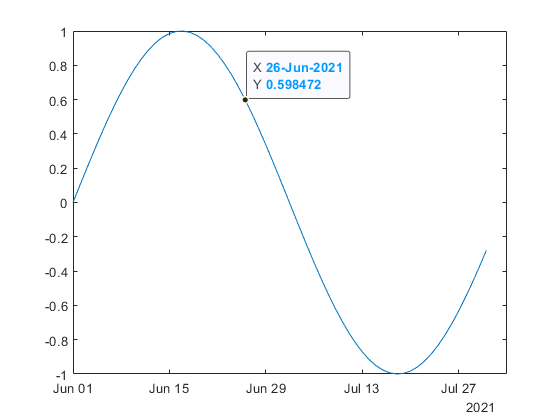

To export the cursor data to the workspace, right-click the data tip and select **Export Cursor Data to Workspace**. This action exports the cursor data to a structure in the workspace.

The `cursor_info.Position` field represents the cursor data as a pair of numeric values. The `Axes` object associated with the plot has the information needed to convert the numeric value of the *x*-coordinate to a `datetime` value. Get the `Axes` object for the plot. Then pass the numeric *x*-coordinate and the *x*-axis from the `Axes` object to `num2ruler`.

You do not need to convert the numeric *y*-coordinate, `cursor_info.Position(2)` because the *y*-values in this plot are numeric.

## Plot Dates and Times from File

Data files such as spreadsheets and CSV files often store dates and times as formatted text. When you read in data from such files, you can convert text representing dates and times to `datetime` or `duration` arrays. Then you can create plots of that data.

For example, create a plot of data from the example data file `outages.csv`. This CSV file contains six columns of data. Two columns contain text that represent dates and times.

The recommended way to read data from a CSV file is to use the `readtable` function. This function reads data from a file and returns it in a table.

Read in `outages.csv`. The `readtable` function automatically converts the text in the `OutageTime` and `RestorationTime` columns to `datetime` arrays. The columns that represent numbers (`Loss` and `Customers`) are read in as numeric arrays. The remaining columns are read in as strings. The table stores the columns of data from `outages.csv` in table variables that have the same names. Finally, sort the rows of `T` by the dates and times in `OutageTime` by using the `sortrows` function. If a table is not sorted by time, then it is a best practice to sort the table by time before plotting or analyzing the data.

T = readtable("outages.csv","TextType","string");
T = sortrows(T,"OutageTime")

You can access table variables by using dot notation, referring to a table variable by name. With dot notation, you can treat table variables like arrays.

Plot the power loss against outage time. To access these variables from the table, use dot notation.

plot(T.OutageTime,T.Loss)

Calculate the durations of the power outages and plot them against `OutageTime`. To calculate the durations, subtract `OutageTime` from `RestorationTime`. The result, `OutageDuration`, is a `duration` array, because arithmetic with `datetime` values produces lengths of time as output. Some of these outage durations are long, so change the format of the *y*-axis tick values from hours to years by using `ytickformat`. The fact that some outages apparently last for years indicates there might be a few questionable data values in the file. Depending on how you plan to analyze the data, you can either reprocess it in some way or remove the rows containing bad values.

OutageDuration = T.RestorationTime - T.OutageTime;
plot(T.OutageTime,OutageDuration)
ytickformat("y")

*Copyright 2012-2021 The MathWorks, Inc.*